# Code for speckle reduction using Error diffusion

% 20230803 Kyosik_Min
% code for share
% “Quality enhancement of binary-encoded amplitude holograms by using error diffusion”

clear; 
clc;
tic
addpath('./myFunctions')
addpath('./myFunctions_ED')

## For gamma correction in figures

gammaAS = 0.3;      % angular spectrum gamma 
gammaRec = 2;       % reconstruction gamma (1: amplitude, 2: intensity)

## System Paramters (all length units are meter)

wavelength = 532e-9;
px=7.6e-6; py=px;

Nxx=768+1;  
Nyy=768+1;            % Resolution of hologram % from etri code (1 added to make it odd)

Nx = 1920+1; Ny = 1080+1;         % Resolution of DMD


## Object paramters

dataType = 'rgb + depth map';               %'rgb + depth map';
fileName_rgbd = 'Cat'; % [fileName_rgbd, '_rgb.bmp'] for rgb, [fileName_rgbd, '_d.bmp'] for depth map

distance_hologram_object_plane = 0.03;  %


## Setting for carrier wave range 


%%%%%%% carrier wave location setting %%%%%%%%%
% other location is also possible as controlling the variable below

minFxIdx = floor((Nx)/2);   
maxFxIdx = minFxIdx; % for time-multiplexing (multiple carrier waves)
stepFxIdx = floor((Nx)/8);            
rangeFxIdx = [minFxIdx, maxFxIdx, stepFxIdx]; % for time-multiplexing (multiple carrier waves)


minFyIdx = floor((Ny+1)/4);
maxFyIdx = minFyIdx;                
stepFyIdx = floor((Ny/Nx)*stepFxIdx);
rangeFyIdx = [minFyIdx, maxFyIdx, stepFyIdx];

## directory for saving hologram mat files

dirName = '.';

## Load object

if strcmp(dataType, 'rgb + depth map')
    rgb = imresize(imread([fileName_rgbd, '_rgb.bmp']),[Nyy,Nxx]);

    rgb = double(rgb2gray(rgb))/255;                    
    rgbDMD = zeros(Ny,Nx);
    startY = round(Ny/2) - round(Nyy/2);
    startX = round(Nx/2) - round(Nxx/2);
    rgbDMD(startY + (1:Nyy), startX + (1:Nxx)) =rgb;
    rgb = rgbDMD;
    
    
    if exist([fileName_rgbd, '_d.bmp'],'file')          
        depthMap = imresize(imread([fileName_rgbd, '_d.bmp']),[Ny,Nx]);
        depthMap = double(depthMap);
        depthMap = depthMap(:,:,1);
        depthMap = distance_hologram_object_plane + 0.05*depthMap/255;  
        % if you have a depthmap for object
        % you can set your depthmap configuration
    else
        
        depthMap(:,(1:round(Nx/2)-1)) = distance_hologram_object_plane*ones(Ny,round(Nx/2)-1);
        depthMap(:,(round(Nx/2):Nx)) = distance_hologram_object_plane*(ones(Ny,round(Nx/2))*(1/3));
        disp(['There is no depth map file so just assume ',num2str(distance_hologram_object_plane),'meter depth object'])
    end
end

There is no depth map file so just assume 0.03meter depth object


## CGH calculation and save to files

if strcmp(dataType, 'rgb + depth map')
    fn_saveHologramRGBD(rgb, depthMap, wavelength, px, py, Nx,Ny, rangeFxIdx, rangeFyIdx, dirName); %Carrier wave 위치
end

## Prepare wp for error diffusion

error diffusion 계수 w를 얻자


%%%%%%%% Step 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% design the Weight of error diffusion
% there are many choices you can choose

%[wc, NwX, NwY] = getWc(Nx,Ny, 'Floyd_Steinberg');
[wc, NwX, NwY] = getWc(Nx,Ny, 'Single_Right');
%''kyosik_cross', 'kyosik_leftupper', 'kyosik_rightupper', 'kyosik_rightupperEX', 'kyosik_rightupperEX2'
    %'Iterative_Deisgn', 'NwX',2, 'NwY',0, 'halfBW',50, 'maxIter',50, 'verbose',0);

%%%%%%% Step 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Scale the filter in angular frequency maintaining the center
% scaleW( ~, scaleX, scaleY) 
% scaleX, scaleY is natural number

[wc, NwX, NwY] = scaleW(wc, NwX, NwY, 1, 1); 



## aperture mask configuration in 4-f system

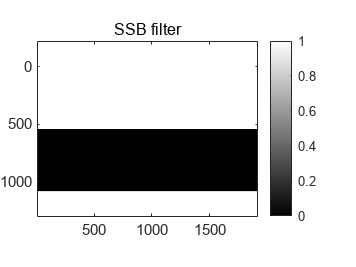

maskSSB = zeros(Ny, Nx);
% maskHp = zeros(Ny, Nx);

maskSSB(1:floor(Ny/2),:)=1;     % for single-side-band
figure(); imagesc(maskSSB); axis equal; title('SSB filter'); colorbar();

## Load hologram files and save encoded and binarized hologram to files

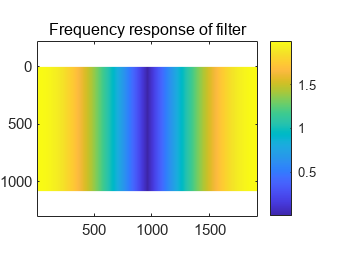

if ~exist([dirName,'/encoding/single'],'dir')
    mkdir([dirName,'/encoding/single']);
end

i = 0;


cuFxIdx = maxFxIdx;
cuFyIdx = maxFyIdx;
        i = i+1;
        
        fileName = [dirName,'/hologram_cuFxIdx',num2str(cuFxIdx),'_cuFyIdx',num2str(cuFyIdx)];
        load(fileName,'hologram');

        
        % SSB filtering
        hologramSSB = myifft2(myfft2(hologram).*maskSSB);

        %dataToBeEncoded = cf2dataToBeEncoded(hologram);
        % complex field must be modified to be encoded
        dataToBeEncoded = cf2dataToBeEncoded(hologramSSB);
        
        % binarization threshold
        threshold = 0.55; 
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%% shifting the center of weight %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        FTData = abs(myfft2(dataToBeEncoded));
        FTData(541,961) = 0; % to make DC to be a 0
        % if the resolution of DMD is changed, this line should be changed
        % as well

        [maxpeakY,maxpeakX] = find(abs(myfft2(dataToBeEncoded)) == max(max(FTData)));
        wp = shiftW(wc, 0, maxpeakY-541);

        Hp = W2H(myfft2(wp));
        figure(); imagesc(abs(Hp)); axis equal; colorbar(); title('Frequency response of filter');

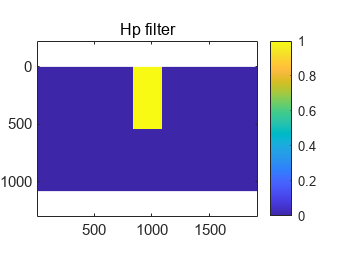

        maskHp = zeros(Ny, Nx);
        maskHp(abs(Hp)<0.4)=1;          % "0.4" is hyperparameter
        maskHp = maskHp.*maskSSB;
        figure(); imagesc(maskHp); axis equal; title('Hp filter'); colorbar();

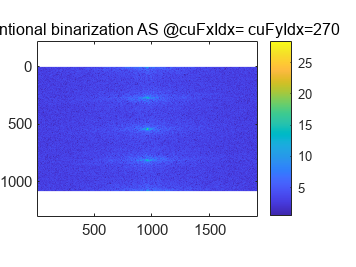



        %%%%%%%%%%%%%%%%%%%%%%%%%%%%% binarization of the hologram %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % conventional binarization
        beConv = binarize(real(dataToBeEncoded), threshold);
        DMD = zeros(1080,1920);
        DMD(:,:) = beConv(1:end-1, 1:end-1); %we already added 1 in line 15
        fileName = [dirName,num2str(cuFyIdx)];
        %imwrite(gather(DMD),[fileName,'.bmp'])
        figure(); imagesc(abs(myfft2(beConv)).^gammaAS); axis equal; colorbar(); title(['conventional binarization AS @cuFxIdx=',' cuFyIdx=',num2str(cuFyIdx)]);

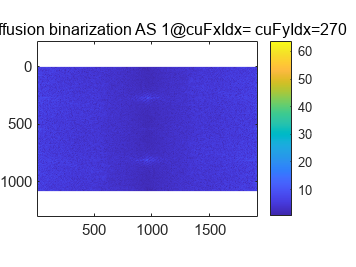

        
        % error diffusion binarization
        beED = errorDiffusion(real(dataToBeEncoded), wp, NwX, NwY, threshold);
        DMD = zeros(1080,1920);
        DMD(:,:) = beED(1:end-1, 1:end-1); 
        % we already added 1 in line 15

        fileName = [dirName,'_cuFyIdx',num2str(cuFyIdx)];
        %imwrite(gather(DMD),[fileName,'.bmp'])
        figure(); imagesc(abs(myfft2(beED)).^gammaAS); axis equal; colorbar(); title(['error diffusion binarization AS 1@cuFxIdx=',' cuFyIdx=',num2str(cuFyIdx)]);        

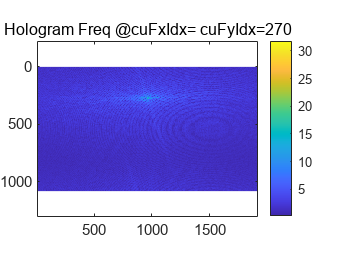

        
        figure(); imagesc(abs(myfft2(hologram)).^gammaAS); axis equal; colorbar(); title(['Hologram Freq @cuFxIdx=',' cuFyIdx=',num2str(cuFyIdx)]);

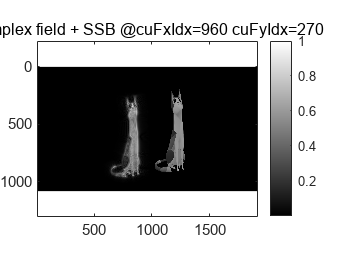

        % for check carrier wave Freq. 
        
        %%%%%%%%%%%%%%%%%%% This part is for the test and debugging %%%%%%%%%%%%%%%%%%  
        z=distance_hologram_object_plane;
        zo=z/3;
        
        % reconstruction of complex field (ideal case)
        [rec,~] = FresnelPropagation_as(hologramSSB, px, py, zo, wavelength);
        rec = rec./(max(max(rec)));
        figure(); imagesc(abs(rec)); colormap(gray); axis equal; colorbar(); title(['complex field + SSB @cuFxIdx=',num2str(cuFxIdx),' cuFyIdx=',num2str(cuFyIdx)]);

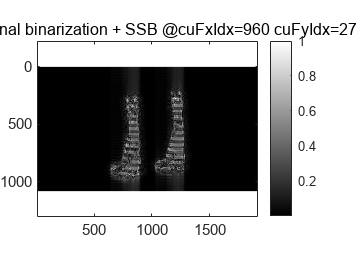

        
        % conventional binarization with the simple thresholding case
        % + SSB filter
        beConvSSB = myifft2(myfft2(beConv).*maskSSB);
        [rec,~] = FresnelPropagation_as(beConvSSB, px, py, zo, wavelength);
        rec = rec./(max(max(rec)));
        figure(); imagesc(abs(rec)); colormap(gray); axis equal; colorbar(); title(['conventional binarization + SSB @cuFxIdx=',num2str(cuFxIdx),' cuFyIdx=',num2str(cuFyIdx)]);

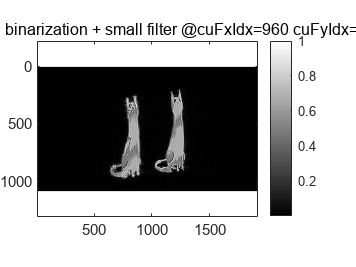


        
      
        % conventional binarization with the simple thresholding case
        % + small filter centered at cuFxIdx, cuFyIdx
        maskSquare = zeros(Ny,Nx); 
        hbw = 125;
        maskSquare( cuFyIdx+(-hbw:hbw),  cuFxIdx+(-hbw:hbw) )=1;
        beConvSquare = myifft2(myfft2(beConv).*maskSquare);
        [rec,~] = FresnelPropagation_as(beConvSquare, px, py, zo, wavelength);
        rec = rec./(max(max(rec)));
        figure(); imagesc(abs(rec)); colormap(gray); axis equal; colorbar(); title(['conventional binarization + small filter @cuFxIdx=',num2str(cuFxIdx),' cuFyIdx=',num2str(cuFyIdx)]);

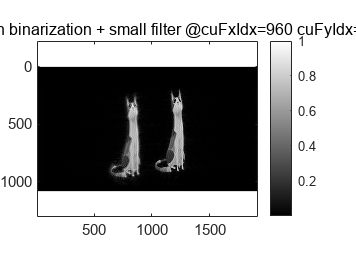

       
        % Error diffusion binarization
        % + small filter
        beEDHp = myifft2(myfft2(beED).*maskHp);
        beEDHp22 = myifft2(myfft2(beED).*maskSquare);
        [rec,~] = FresnelPropagation_as(beEDHp22, px, py, zo, wavelength);
        rec = rec./(max(max(rec)));
        figure(); imagesc(abs(rec)); colormap(gray); axis equal; colorbar(); title(['Error diffusion binarization + small filter @cuFxIdx=',num2str(cuFxIdx),' cuFyIdx=',num2str(cuFyIdx)]);

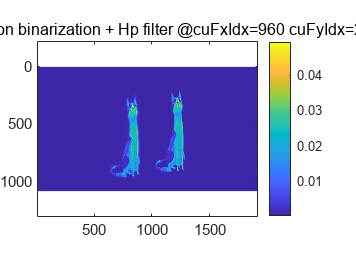

            
        % + Hp filter
        [rec,~] = FresnelPropagation_as(beEDHp, px, py, zo, wavelength);
        figure(); imagesc(abs(rec).^gammaRec); axis equal; colorbar(); title(['Error diffusion binarization + Hp filter @cuFxIdx=',num2str(cuFxIdx),' cuFyIdx=',num2str(cuFyIdx)]);